# Apuntes de Clase - Simulación de colas

Herramientas Matemáticas para el Manejo de la Información

Sesión 11 - 29 de octubre de 2026

# Simulación de la Cola M/M/1

## Aspectos considerados 

Considérese que en una cola de tamaño infinito, un único servidor debe atender una cantidad particular de usuarios y que los tiempos entre arribos consecutivos de los usuarios, se consignan como elementos del vector `tea`. Por ejemplo, 

tea = [1,2,3,7,2,3,8,0,5];

Entonces, el número total de usuarios que atenderá el servidor es:

usuarios = numel(tea)

usuarios = 9

Ahora, considérese que los tiempos de servicio se consignan en cada posición del vector `tds`:

tds = [9,1,4,1,1,5,3,8,2];

Adicionalmente, se definen las siguientes variables:

- `reloj`: instante de tiempo en el que llega cada usuario al sistema.

- `inicio`: instante de tiempo en el que inicia la atención del usuario.

- `salida`: instante de tiempo en el que sale un usuario atendido.

- `espera`: tiempo que tarda un usuario en la línea de espera.

Por lo tanto, el vector `reloj` es:

reloj = cumsum(tea)

reloj =      1     3     6    13    15    18    26    26    31


Y los demás vectores, se deben ir llenando de acuerdo con la disciplina FIFO. Además, para optimizar el acceso a memoria, se sugiere inicializar los vectores:

inicio = zeros(1,usuarios);
salida = zeros(1,usuarios);

Como el primer usuario no tiene que esperar, el tiempo de inicio de él, es:

inicio(1) = reloj(1);

Simulación de la Cola:

for i = 1:usuarios-1
    salida(i) = inicio(i) + tds(i);
    if salida(i)>reloj(i+1)
        inicio(i+1) = salida(i);
    else
        inicio(i+1) = reloj(i+1);
    end    
end

espera = inicio - reloj;
ETw = mean(espera) % Cálculo de la medida de desempeño

ETw = 2.6667

## Prueba con valores fijos

Para verificar el funcionamiento de la cola construida, se considerará la función `xx1`, que toma como parámetros de entrada los vectores:

tea = [1,2,3,7,2,3,8,0,5];
tds = [9,1,4,1,1,5,3,8,2];

y retorna todas las variables consideradas durante la simulación:

Twpromedio = xx1(tea,tds)

tea =      1     2     3     7     2     3     8     0     5


tds =      9     1     4     1     1     5     3     8     2


reloj =      1     3     6    13    15    18    26    26    31


inicio =      1    10    11    15    16    18    26    29    37


salida =     10    11    15    16    17    23    29    37    39


espera =      0     7     5     2     1     0     0     3     6


Twpromedio = 2.6667

## Prueba con valores enteros aleatorios

usuarios = 9;
tea = randi(11,1,usuarios)-1;
tds = randi(11,1,usuarios)-1;
Twpromedio = xx1(tea,tds)

tea =      2     5     9     4     8     2     3     0    10


tds =     10     6     6     2     9     6     4     1     8


reloj =      2     7    16    20    28    30    33    33    43


inicio =      2    12    18    24    28    37    43    47    48


salida =     12    18    24    26    37    43    47    48    56


espera =      0     5     2     4     0     7    10    14     5


Twpromedio = 5.2222

## Observaciones

- La función `xx1`, permite simular una cola de longitud infinita y con un único servidor. No importa cómo estén distribuidos los tiempos entre arribos consecutivos, ni los tiempos de servicio. 

- La función `xx1`, también permite considerar el caso de que varios usuarios lleguen al mismo tiempo.

- Adicionalmente, la función `xx1` permite observar la situación indeseada: $\lambda\geq\mu$.

- Por las razones anteriores, la función `xx1` es una implementación del sistema $X/X/1/\infty/\infty$, en donde las $X$ indican que se pueden aplicar cualquier distribución de arribo y de servicio, incluyendo arribos simultáneos.

# Validación

## Prueba con tiempos exponencialmente distribuidos

lambda = 7;
mu = 8;

usuarios = 100000;
tea = exprnd(1/lambda,1,usuarios);
tds = exprnd(1/mu,1,usuarios);
Twpromedio = xx1(tea,tds,0) % No muestra todos los vectores. Solo retorna Twpromedio.

Twpromedio = 0.8659

Como se consideran tiempos exponencialmente distribuidos, el valor indicado en `Twpromedio` se debe comparar con:


$$E[T_w]=\frac{1}{\mu-\lambda}-\frac{1}{\mu}$$


(1/(mu-lambda))-(1/mu)

ans = 0.8750

# Actividad 3 del segundo trabajo grupal

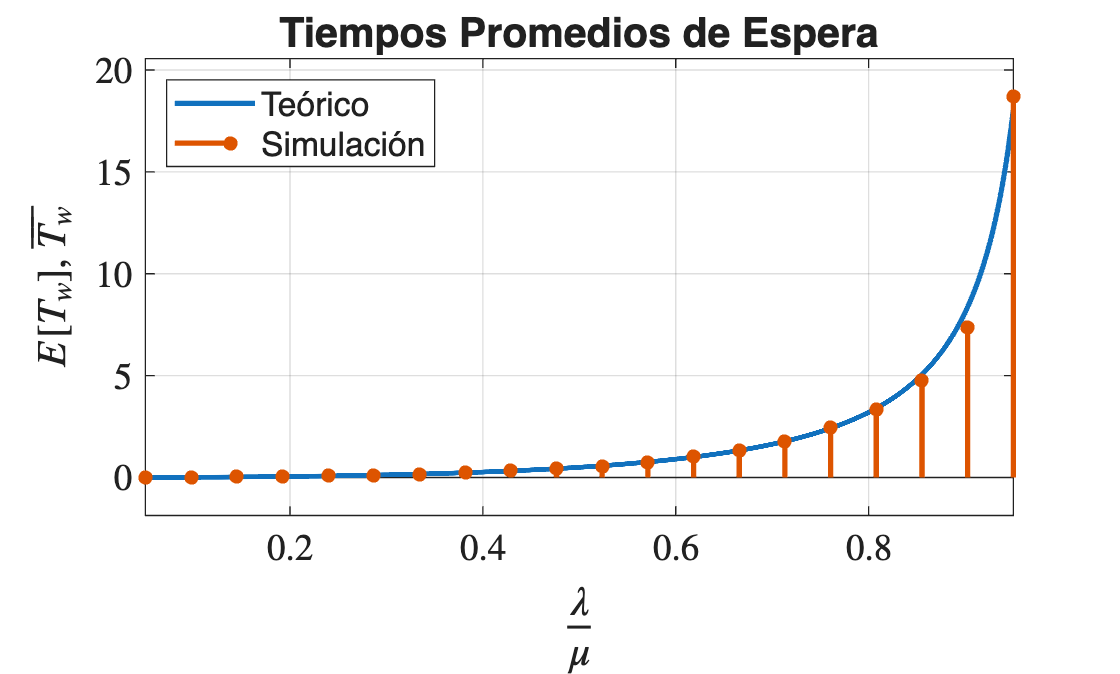

figure(1);
usuarios = 100000;
lambda = 1;
simulaciones = 20; % # de comparaciones

% Resultado Teórico: E[Tw]
A = linspace(0.05,0.95,10000); % cambiar el 0.95 por el A sugerido en clase
mu = lambda./A;
teorico = 1./(mu-lambda)-1./mu; % usar el valor teórico según la cola asignada
superplot(A,teorico);
hold on;

% Resultado de Simulación: Twpromedio
A = linspace(0.05,0.95,simulaciones); % cambiar el 0.95 por el A sugerido en clase
mu = lambda./A;

resultadosimulacion = zeros(1,simulaciones);
for n = 1:simulaciones
    tea = exprnd(1/lambda,1,usuarios);
    tds = exprnd(1/mu(n),1,usuarios);
    resultadosimulacion(n) = xx1(tea,tds,0); % usar su función 
end

superstem(A,resultadosimulacion,'Tiempos Promedios de Espera',...
    '$\frac{\lambda}{\mu}$','$E[T_w],\:\overline{T_w}$');
xlim([0.05,0.95]); % Se debe cambiar el 0.95, por el límite sugerido en la línea 13
hold off;

legend({'Teórico','Simulación'},'Location','northwest');

# Función Cuantil (*Quantile*)

La función cuantil, $Q(p)$, es la inversa de la Función de Distribución Acumulativa. Esto es, para la variable aleatoria:


$$X: \Omega \to \mathbb{R}$$


Con distribución:


$$F_X(x) = P[X\leq x] = p$$


la función cuantil se define como:


$$Q_X(p) := F_X^{-1}(p)$$


## Función Cuantil de la distribución exponencial

Considérese la variable aleatoria:


$$T: \Omega \to \mathbb{R}$$



$$T\sim \text{Exp}(t;\lambda)$$


La Función de Distribución Acumulativa de la variable aleatoria exponencial es:


$$F_T(t) = 1-\exp(-\lambda t) = p$$


Despejando el valor de $t$, se obtiene la expresión analítica para la función cuantil:


$$t = -\frac{1}{\lambda}\ln(1-p)$$



$$Q_T(p) = -\frac{1}{\lambda}\ln(1-p)$$


## Gráfica de la función Cuantil de la variable aleatoria exponencial

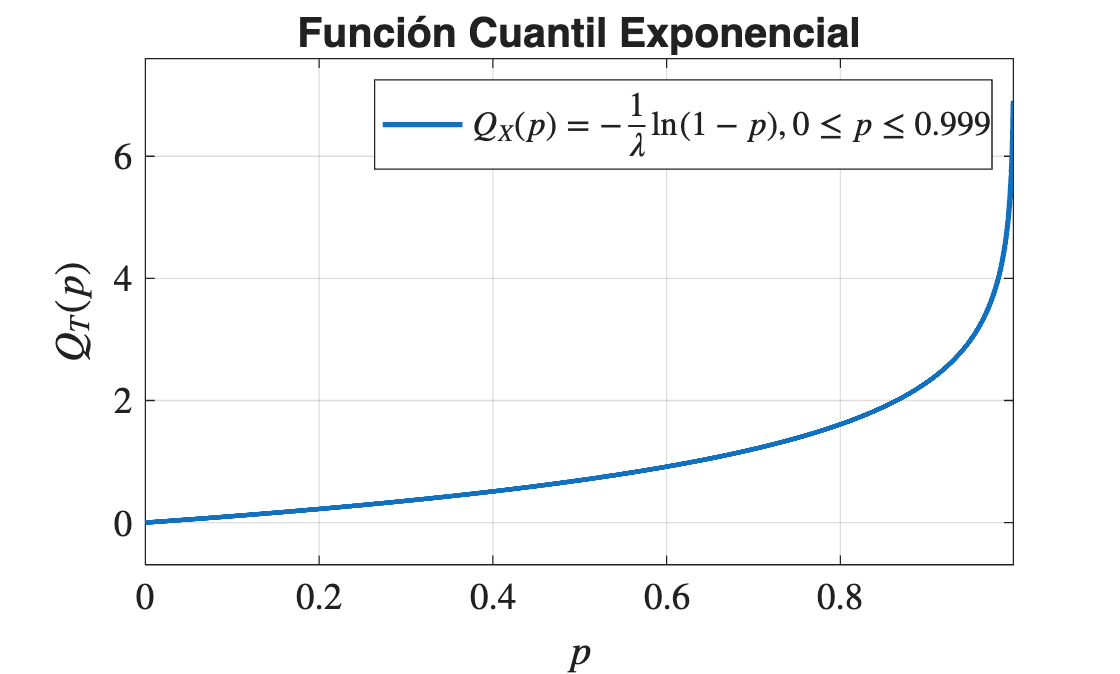

figure(2);
lambda = 1;
p = linspace(0,0.999,10000);
Q = -log(1-p)/lambda; % En MATLAB, log = logaritmo natural y log10 es logaritmo en base 10
superplot(p,Q,'Función Cuantil Exponencial',...
    '$p$','$Q_T(p)$');
legend('$Q_X(p)=-\frac{1}{\lambda}\ln(1-p),\, 0\leq p\leq 0.999$',...
    'interpreter','latex');

## Observaciones

La función cuantil puede emplearse para:

- Describir una variable aleatoria.

- Generar números aleatorios. Si $p\sim \mathcal{U}(0,1)$; entonces, $Q_X(p)$ presenta la misma distribución de la variable aleatoria $X$.

- Revisar si una muestra aleatoria presenta una distribución particular, por ejemplo con la *qqplot*.

# Método de la Inversa

El método de la inversa se puede resumir en los siguientes dos pasos: 

- Generar un número aleatorio uniformemente distribuido con parámetros $a=0$ y $b=1$.

- Emplear el número obtenido en el primer paso, como parámetro de entrada de la función cuantil.

## Generación de datos exponencialmente distribuidos

Para ilustrar el método de la inversa, se utilizará la función `randomexponencial` que se encuentra al final de este *Live script*. A continuación, se comparan gráficamente las pdf de una muestra aleatoria generada por `randomexponencial` y la de una exponencial.

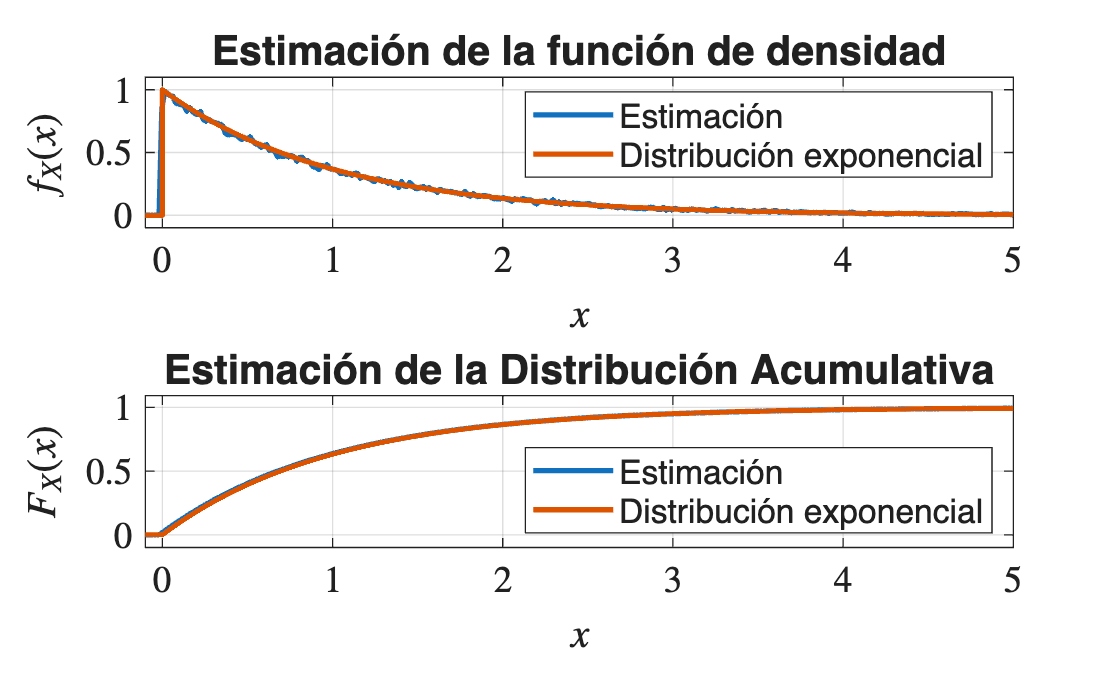

figure(3);
lambda = 1;
muestra = randomexponencial(lambda,1,100000);
pdfcdfcontinua(muestra,-0.1,5);
subplot(2,1,1)
hold on;
t = linspace(-0.1,5,10000);
pdf = exppdf(t,1/lambda);
superplot(t,pdf);
hold off;
legend('Estimación','Distribución exponencial');
subplot(2,1,2)
hold on;
t = linspace(-0.1,5,10000);
cdf = expcdf(t,1/lambda);
superplot(t,cdf);
hold off;
legend('Estimación','Distribución exponencial',...
    'Location','southeast');

# Q-Q plot

Es la gráfica de los cuantiles de una muestra aleatoria contra los cuantiles de una referencia (cuando no se indica, la referencia es normal estándar).

## Datos normalmente distribuidos

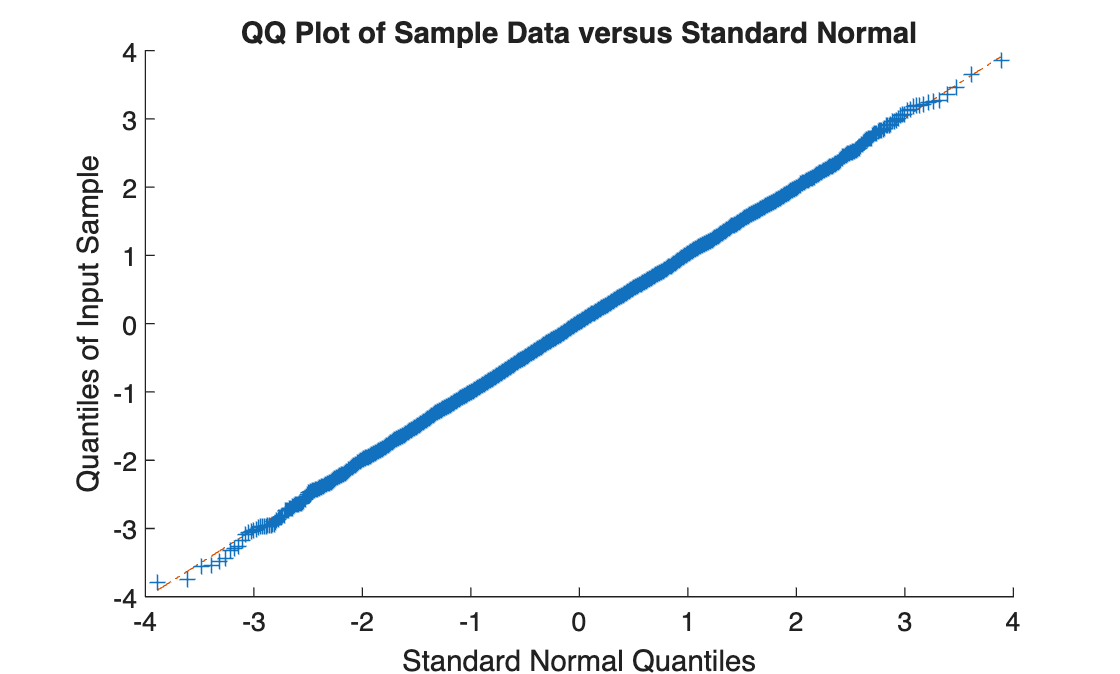

figure(4);
mu = 0;
sigma = 1;
muestra = mu + sigma*randn(1,10000);
qqplot(muestra);

## Datos exponencialmente distribuidos

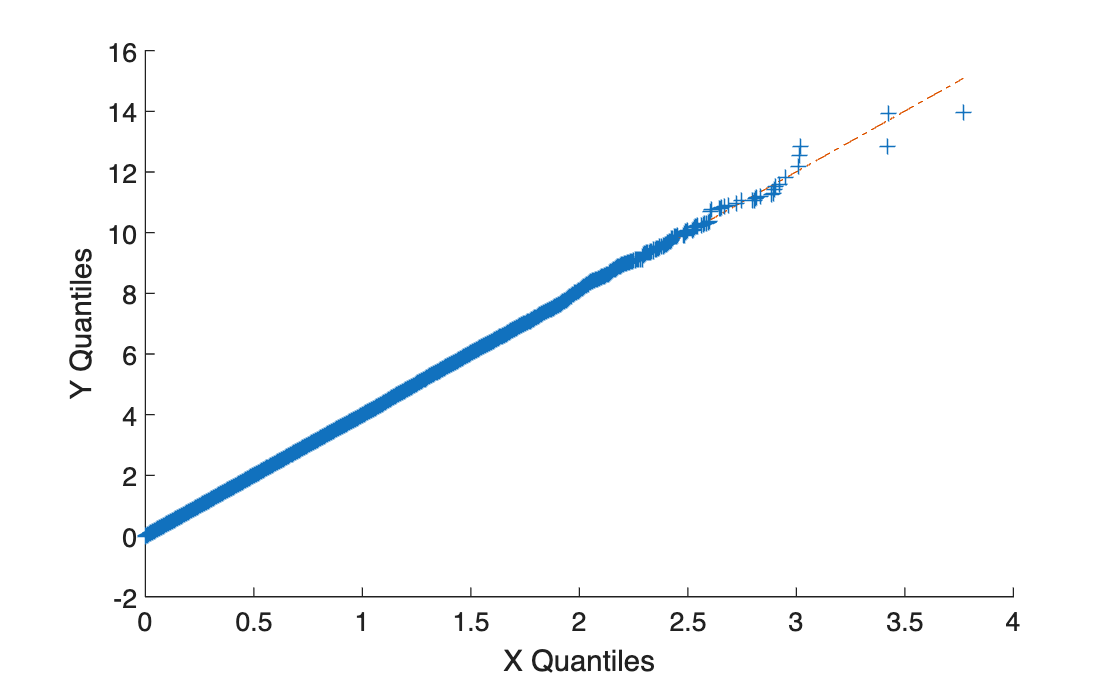

figure(5);
lambda = 4;
referencia = exprnd(1,1,1000000);
muestra = randomexponencial(lambda,1,1000000);
qqplot(muestra,referencia);

# Generación de números aleatorios con distribuciones muestrales

El método de la transformación inversa es útil, toda vez que se pueda calcular la función cuantil. Lamentablemente, las variables aleatorias que mejor modelan a la realidad no se suelen describir con funciones analíticas. Es por esto que se opta por utilizar algún método numérico que permita estimar las funciones cuantiles de manera empírica.    

## Código base

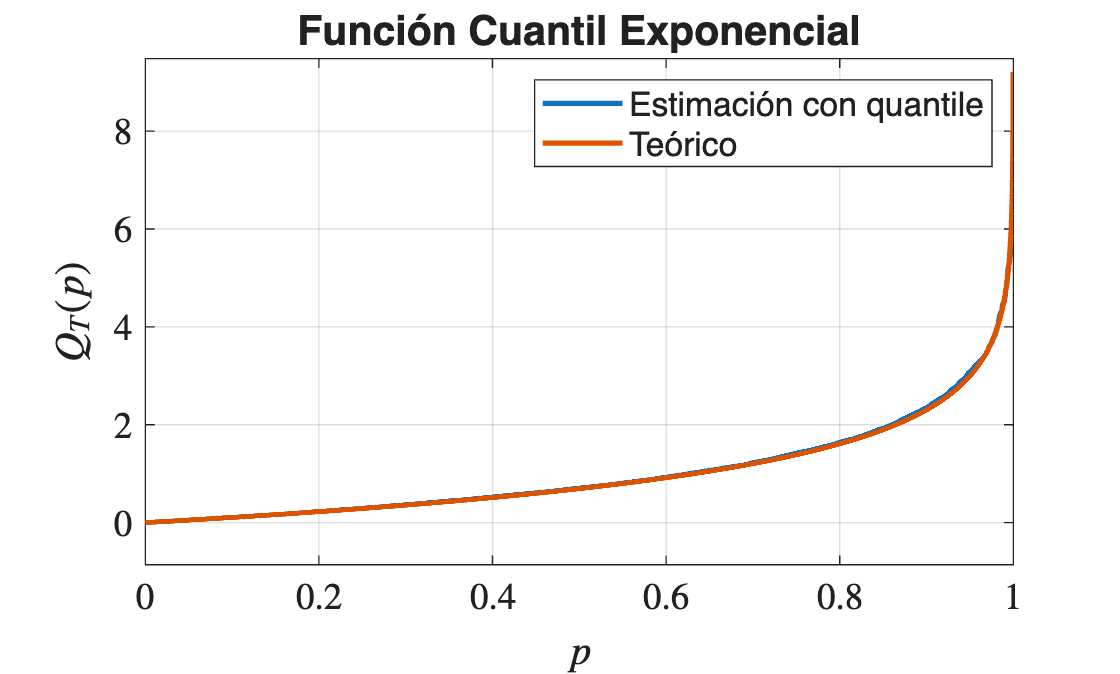

figure(6);
lambda = 1;
p = linspace(0,1,10000);
muestra = exprnd(1/lambda,1,10000);
Q = quantile(muestra,p);
superplot(p,Q,'Función Cuantil Exponencial',...
    '$p$','$Q_T(p)$');
teorica = -log(1-p)/lambda;
hold on;
superplot(p,teorica);
hold off;
legend('Estimación con quantile','Teórico');

## Función propuesta

type superfuncion.m


function [] = superfuncion(datos,nombre)
switch nargin
    case 0
        disp('Falta el vector de datos');
        return;
    case 1
        nombre = 'aleatorio';
end

p = linspace(0,1,100000);
datos = 1.0000000001*datos(:)'; % Materia de Investigación
numero = quantile(datos,p);

encabezado = ['function y = ',nombre,'(m,n)'];
cuerpo = 'numero = [';
final = '];if m==1, y = transpose(numero(randi(numel(numero),m,n))); else, y = numero(randi(numel(numero),m,n));end;end';


fid = fopen([nombre,'.m'],'w');

%fprintf(fid,'%s\n%s\n%10.8f\n%s\n',encabezado,cuerpo,numero,final);
fprintf(fid,'%s\n%s\n%s\n%s\n',encabezado,cuerpo,numero,final);
fclose(fid);
disp([nombre,'.m codificado. Revisa tu carpeta de MATLAB, por favor.']);
disp(['Luego puedes ejecutar: ',nombre,'(m,n).']);
end


## Prueba de `superfuncion`

Función que genera datos aleatorios exponencialmente distribuidos:

muestra = exprnd(1,1,1000000);
superfuncion(muestra,'exponencialrnd');

exponencialrnd.m codificado. Revisa tu carpeta de MATLAB, por favor.
Luego puedes ejecutar: exponencialrnd(m,n).


Prueba de la función codificada:

exponencialrnd(4,5)

ans =     0.6551    2.7281    0.7586    0.1287    0.7153
    0.0159    3.0062    0.9943    0.7312    0.0860
    0.4359    1.0444    1.1443    1.4228    0.1582
    3.0945    0.0447    0.7124    0.0108    0.7939


QQplot de la función codificada:

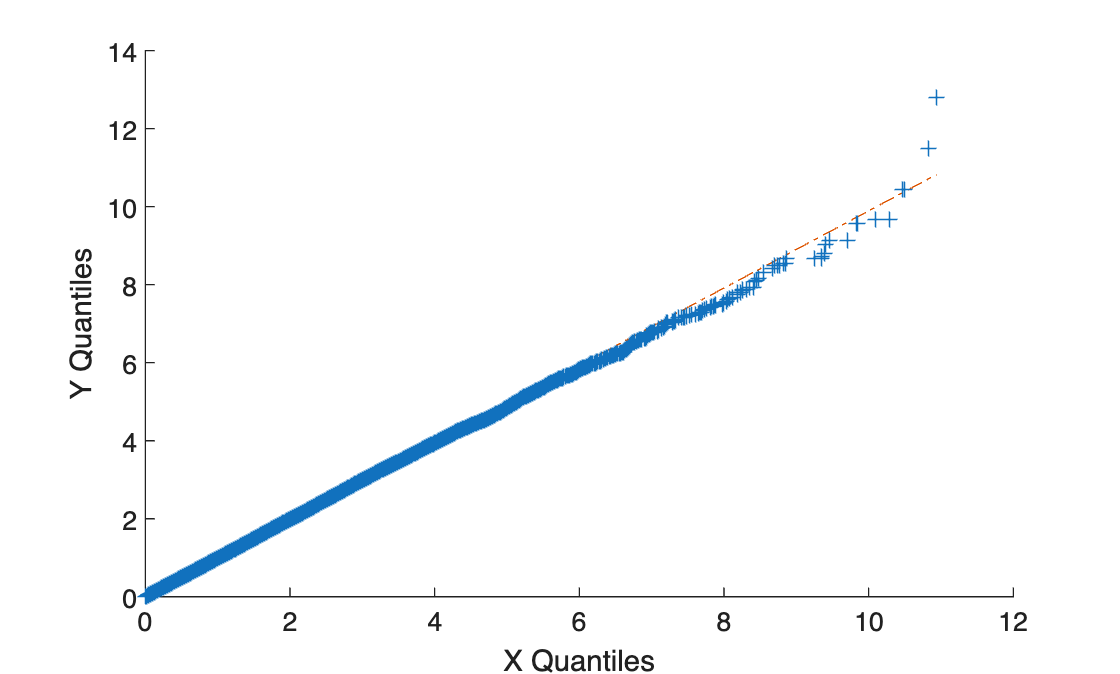

muestra = exponencialrnd(1,100000);
referencia = exprnd(1,1,100000);
qqplot(referencia,muestra);

# Actividad 4 del trabajo grupal

## Distribución de la muestra:

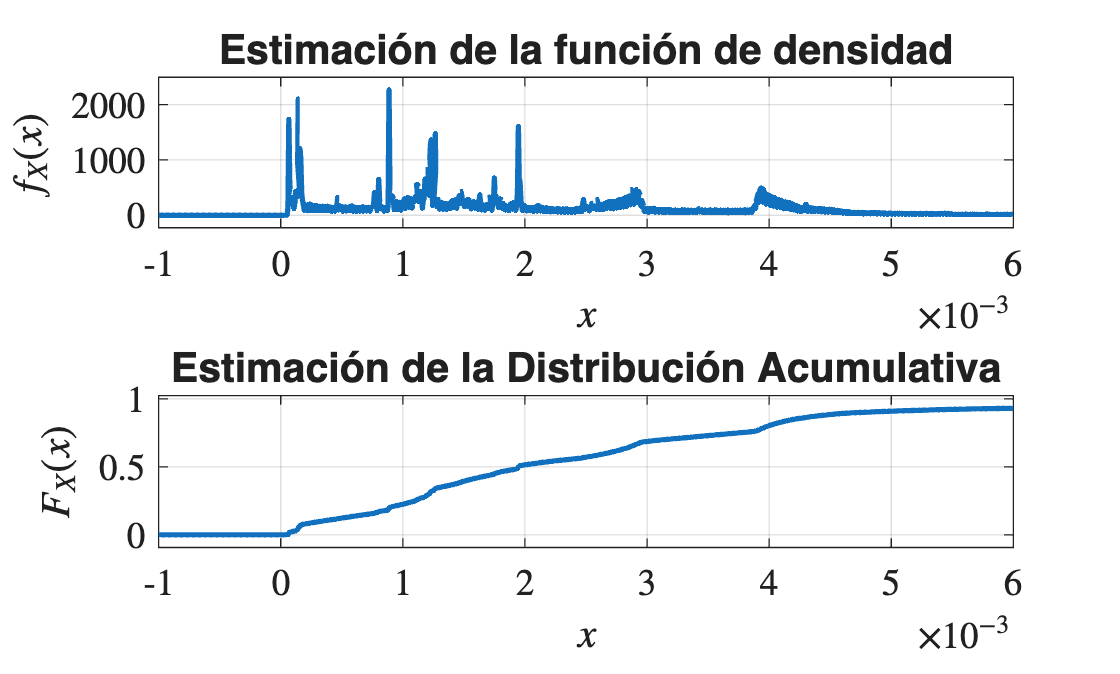

datos = load('BCpAug89.TL'); % Se deben cargar los cuatro archivos. Este ejemplo es para el de agosto
muestra = diff(datos(:,1)'); % Vector tea
figure(7);
pdfcdfcontinua(muestra,-0.001,0.006);

## Codificación de la función

superfuncion(muestra,'agostornd'); % Cambiar el nombre del archivo

agostornd.m codificado. Revisa tu carpeta de MATLAB, por favor.
Luego puedes ejecutar: agostornd(m,n).


## Distribución de la función codificada

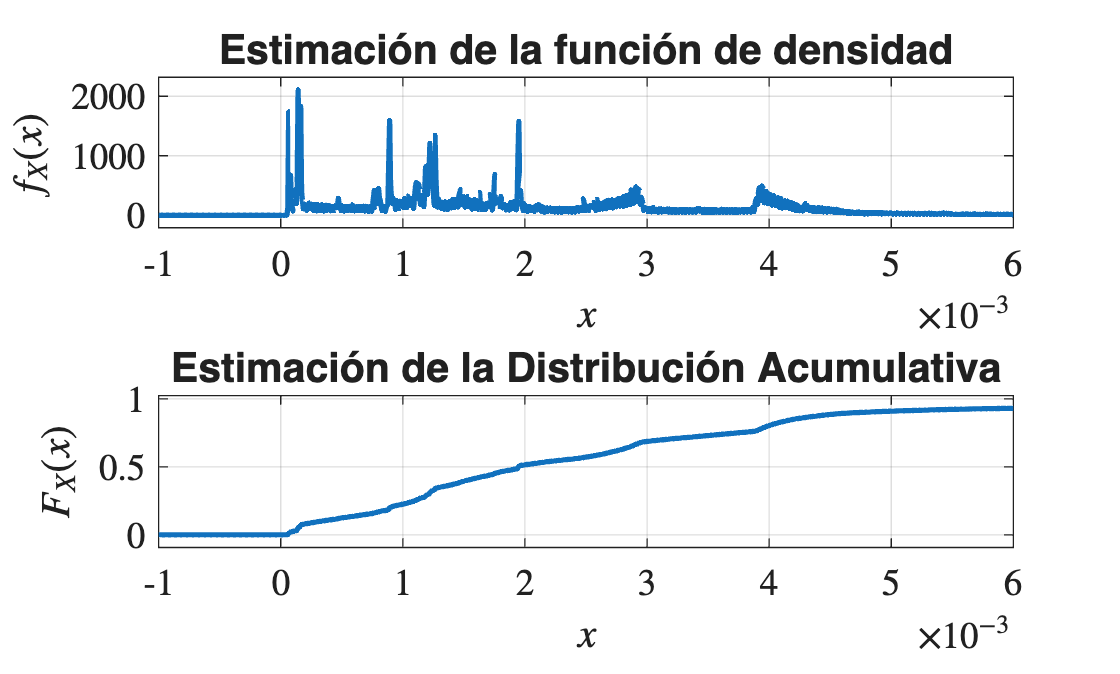

figure(8);
muestraagosto = agostornd(1,1000000); % Utiliza el archivo generado por superfuncion
pdfcdfcontinua(muestraagosto,-0.001,0.006);

## QQplot de la función codificada

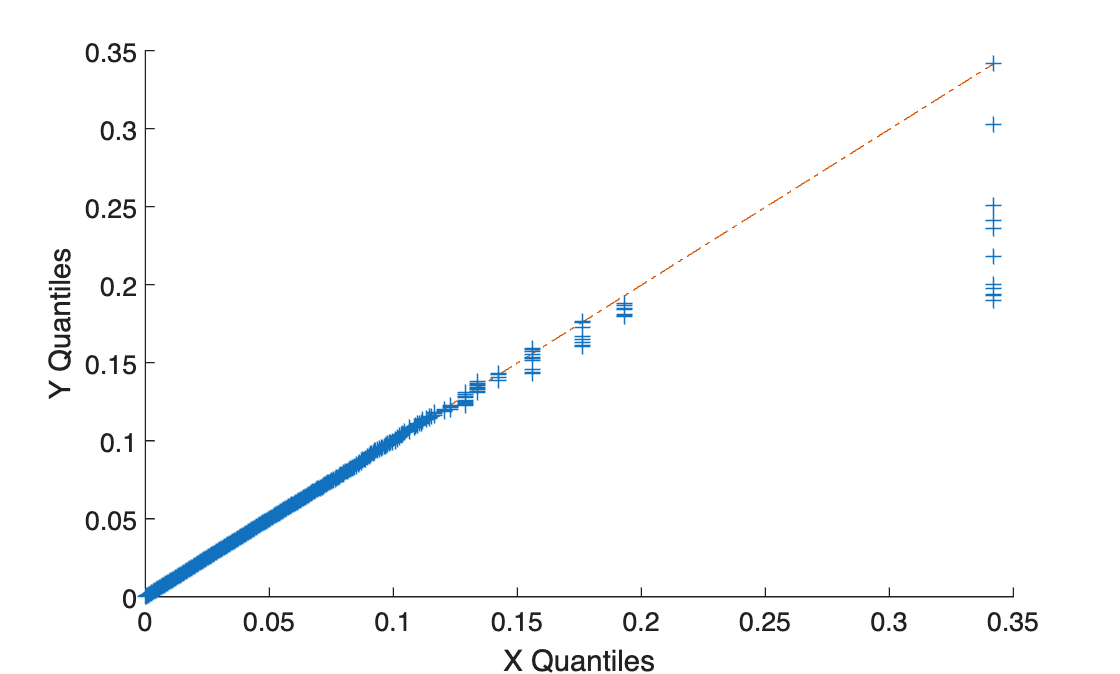

figure(9);
muestraagosto = agostornd(1,1000000);
qqplot(muestraagosto,muestra);

# Actividad 5 del trabajo grupal

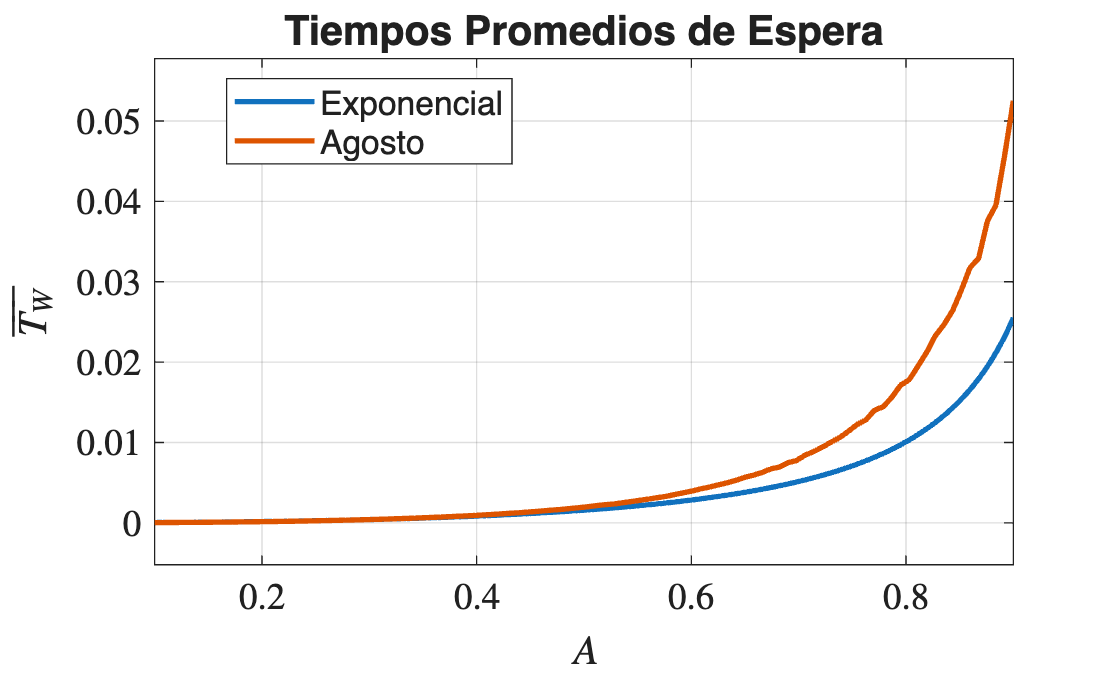

datos = agostornd(1,1000000); % Se debe hacer la prueba con las cuatro funciones
lambda = 1/mean(datos);
Amin = 0.1;
Amax = 0.9; % Cambiar el valor por el sugerido en clase
simulaciones = 100;
A = linspace(Amin,Amax,simulaciones);
mu = lambda./A;
usuarios = 1000000;
tiempomedio = zeros(1,numel(mu));
for n = 1:numel(mu)
    tea = agostornd(1,usuarios); % El archivo generado por superfuncion
    tds = exprnd(1./mu(n),1,usuarios);
    tiempomedio(n) = xx1(tea,tds,0); % La función de la cola asignada a su grupo
end
A = linspace(Amin,Amax,1000);
mu = lambda./A;
teorico = 1./(mu-lambda)-1./mu; % Valor teórico obtenido para la cola
figure(5);
superplot(A,teorico,...
    'Tiempos Promedios de Espera','$A$',...
    '$\overline{T_W}$');
hold on;

A = linspace(Amin,Amax,simulaciones);
superplot(A,tiempomedio);
hold off;

legend({'Exponencial','Agosto'},...
    'location','best');
xlim([Amin Amax]);

## Fecha de entrega del segundo trabajo grupal

12 de noviembre de 2026

# Funciones

Función `xx1`. Permite realizar la simulación de una cola de un solo servidor, con línea de espera infinita, conociendo los vectores de tiempo entre arribos, `tea`; y tiempos de servicio, `tds`. Si la variable `mostrar` es igual a 1, se imprime, en la ventana de comandos, el contenido final de los vectores que se usaron durante la simulación.

function [ETw] = xx1(tea,tds,mostrar)
    switch nargin
        case 2
            mostrar = 1;
    end
    usuarios = numel(tea);
    reloj = zeros(1,usuarios);
    inicio = zeros(1,usuarios);
    salida = zeros(1,usuarios);
    espera = zeros(1,usuarios);
    reloj = cumsum(tea);
    inicio(1) = reloj(1);
    salida(1) = inicio(1)+tds(1);
    for i = 1:usuarios-1
        if reloj(i+1) > salida(i)
            inicio(i+1) = reloj(i+1);
        else
            inicio(i+1) = salida(i);
        end
        salida(i+1) = inicio(i+1) + tds(i+1);
    end
    espera = inicio - reloj;

    ETw = mean(espera);
    
    if mostrar == 1
        tea
        tds
        reloj
        inicio
        salida
        espera
    end    
end

Función que utiliza el método de la inversa para generar muestras aleatorias exponencialmente distribuídas con parámetro `lambda`.

function y = randomexponencial(lambda,m,n)
    y = -log(1-rand(m,n))/lambda;
end